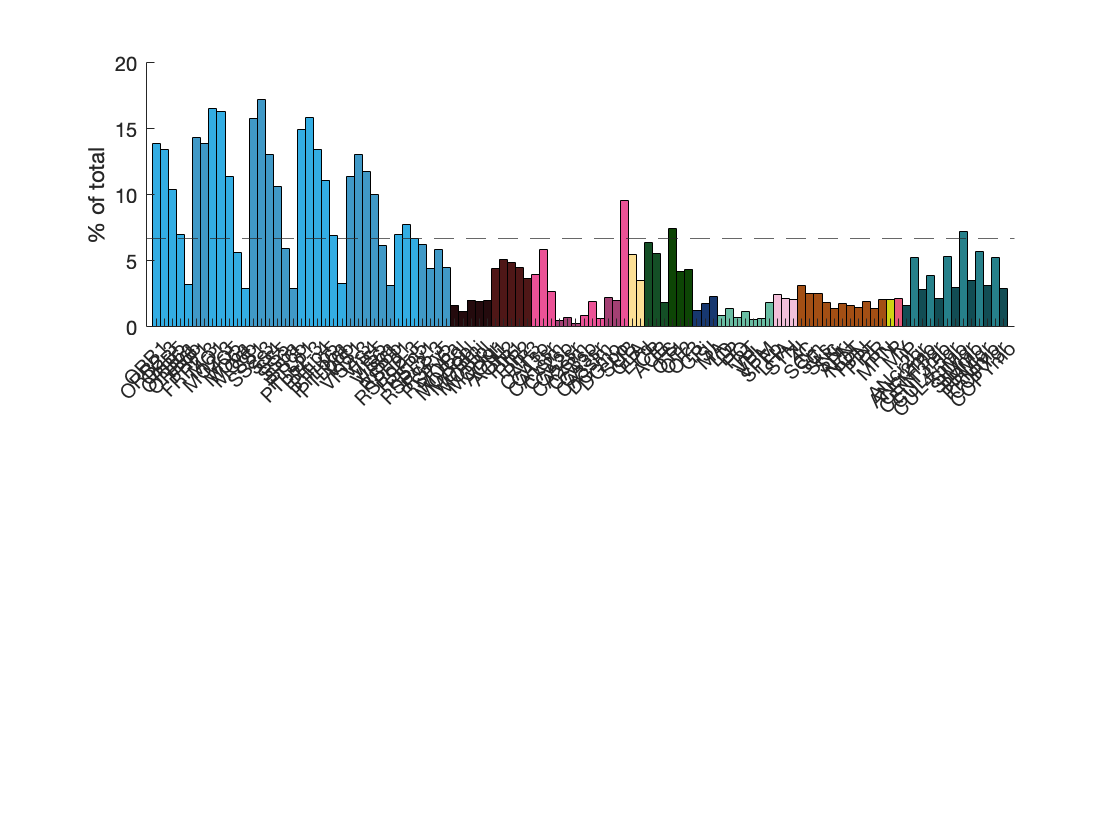

clf;
homedir='/Volumes/Users/homes/Edita/Stats';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';
startRow = 1;

data=dir('long_lived_subtypes_percentage_ofall.csv');
data = readtable(data.name);


subt_name = data(1:106,1);
subt_name = table2array(subt_name);
subt_names_cat=categorical(subt_name);
r_value = data(1:106,2);
r_value = table2array(r_value);
c = data(1:106,3:5);
c = table2array(c);
nregions = length(subt_name);


subplot(2,1,1)
b=bar(r_value,1,"FaceColor","flat");
set(b,'CData',c);
hold on
xticks([1:1:nregions]);
xticklabels(subt_name);
xtickangle(45);

hold on
b.FaceColor = 'flat';
box("off")
ylabel('% of total')
hold on
yline(6.7,'--')
hold off